%% Load data and set variables
load('Data\mtSpikeTimes.mat');
load('Data\retinaData.mat');

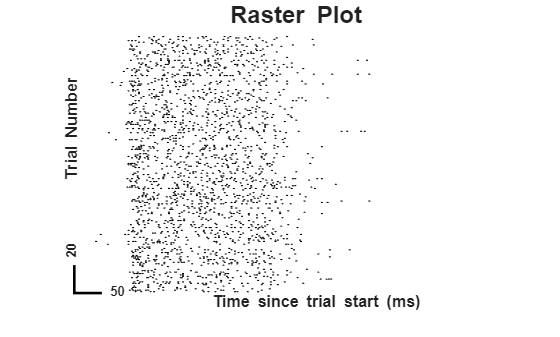

%% 1.1 Raster Plots
figure;
hold on

num_trials = length(mtSpikeTimes);

spike_height = 0.8; 

for trial = 1:num_trials
    if ~isempty(mtSpikeTimes{trial})
        spike_times = mtSpikeTimes{trial} * 1000; % convert to ms

        for s = 1:length(spike_times)
            x = spike_times(s);
            line([x x], ...
                 [trial - spike_height/2, trial + spike_height/2], ...
                 'Color', 'k', 'LineWidth', 1.5);
        end
    end
end

set(gca, 'FontName', 'Arial');
title('\bf Raster Plot', 'FontSize', 18)

text(0, 75, '\bf Trial Number', 'FontSize', 12, 'Rotation', 90)
text(225, -7, '\bf Time since trial start (ms)', 'FontSize', 12)

ylim([-5, num_trials])
xlim([0, 750])

line([0, 0], [0, 20], 'color', 'k', 'LineWidth', 4)
text(0, 20, '\bf 20', 'FontSize', 10, 'Rotation', 90)

line([0, 50], [0, 0], 'color', 'k', 'LineWidth', 2)
text(50, 0, '\bf 50', 'FontSize', 10)

axis off
box off

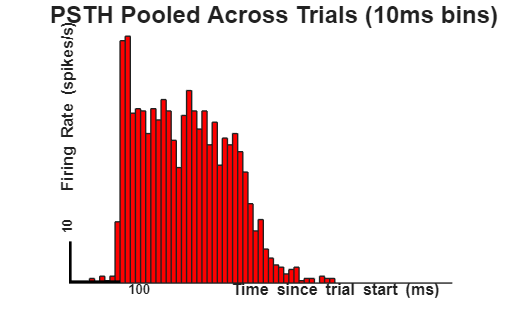

%% 1.2 Peri-Stimulus Time Histograms
% Part A
function func = psth(data, bin_size)
    bins = 0:bin_size:750;
    all_spike_times = [data{:}]; % gets all trials concatenated
    all_spike_times = all_spike_times * 1000;
    spike_counts = histcounts(all_spike_times, bins);
    num_trials = length(data);
    firingRate = spike_counts / ((bin_size / 1000) * num_trials);
    figure;
    b = bar(bins(1:end-1), firingRate, 'histc');
    b.FaceColor = 'red';
    
    set(gca, 'FontName', 'Arial');
    title(sprintf('PSTH Pooled Across Trials (%dms bins)', bin_size), 'FontSize', 18)
    text(0, 20, '\bf Firing Rate (spikes/s)', 'FontSize', 12, 'Rotation', 90)
    text(300, -2, '\bf Time since trial start (ms)', 'FontSize', 12)

    line([0, 0], [10, 0], 'color', 'k', 'LineWidth', 4)
    text(0, 10, '\bf 10', 'FontSize', 10, 'Rotation', 90)
    line([0, 100], [0, 0], 'color', 'k', 'LineWidth', 4)
    text(100, -2, '\bf 100', 'FontSize', 10)
    axis off
    box off
end

psth(mtSpikeTimes, 10);

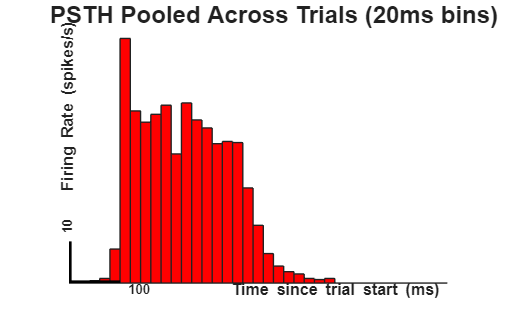

psth(mtSpikeTimes, 20);

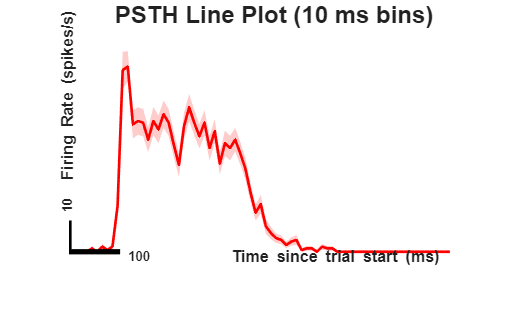


% Part B
function psth_line(data, bin_size)

    bins = 0:bin_size:750;
    num_trials = length(data);
    num_bins = length(bins) - 1;
    trial_rates = zeros(num_trials, num_bins);

    for i = 1:num_trials
        spike_times = data{i} * 1000; % convert to ms
        spike_counts = histcounts(spike_times, bins);
        trial_rates(i, :) = spike_counts / (bin_size / 1000);
    end

    mean_rate = mean(trial_rates, 1);
    sem_rate = std(trial_rates, 0, 1) / sqrt(num_trials);
    bin_centers = bins(1:end-1) + bin_size/2;

    figure;
    hold on;

    fill([bin_centers fliplr(bin_centers)], ...
         [mean_rate + sem_rate, fliplr(mean_rate - sem_rate)], ...
         'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
    plot(bin_centers, mean_rate, 'r', 'LineWidth', 2);

    title(sprintf('PSTH Line Plot (%d ms bins)', bin_size), 'FontSize', 18)
    xlabel('Time since trial start (ms)')
    ylabel('Firing Rate (spikes/s)')

    set(gca, 'FontName', 'Arial');    
    text(0, 20, '\bf Firing Rate (spikes/s)', 'FontSize', 12, 'Rotation', 90)
    text(300, -2, '\bf Time since trial start (ms)', 'FontSize', 12)

    line([0, 0], [10, 0], 'color', 'k', 'LineWidth', 4)
    text(0, 10, '\bf 10', 'FontSize', 10, 'Rotation', 90)
    line([0, 100], [0, 0], 'color', 'k', 'LineWidth', 4)
    text(100, -2, '\bf 100', 'FontSize', 10)
    axis off
    box off
end
psth_line(mtSpikeTimes, 10);

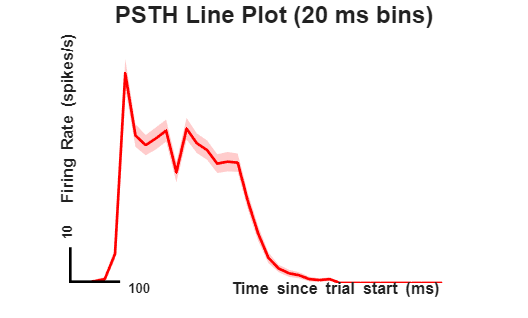

psth_line(mtSpikeTimes, 20);

%% 2.1 Basic Spike Train Statistics
% Part A
num_trials = length(mtSpikeTimes);
count_30 = zeros(num_trials, 1);

for i = 1:num_trials
    spike_times = mtSpikeTimes{i} * 1000; % convert to ms
    if isempty(spike_times)
        continue;
    end
    first_spike = spike_times(1);
    spikes_after = spike_times(spike_times > first_spike);
    count_30(i) = sum(spikes_after <= first_spike + 30);
end
firing_rate_30 = count_30/0.03;
avg_firing_rate_30 = mean(firing_rate_30);

fprintf('Average firing rate (30-ms window): %d \n', avg_firing_rate_30);

Average firing rate (30-ms window): 4.855072e+01 



% Part B
fano_factor_30 = var(counts_30) / mean(counts_30);
fprintf('Fano factor (30-ms window): %d \n', fano_factor_30);

Fano factor (30-ms window): 9.741457e-01 



% Part C
count_300 = zeros(num_trials, 1);

for i = 1:num_trials
    spike_times = mtSpikeTimes{i} * 1000; % convert to ms
    if isempty(spike_times)
        continue;
    end
    first_spike = spike_times(1);
    spikes_after = spike_times(spike_times > first_spike);
    count_300(i) = sum(spikes_after <= first_spike + 30);
end
firing_rate_300 = count_300/0.3;
avg_firing_rate_300 = mean(firing_rate_300);

fprintf('Average firing rate (300-ms window): %d \n', avg_firing_rate_300);

Average firing rate (300-ms window): 4.855072e+00 


fano_factor_300 = var(counts_300) / mean(counts_300);
fprintf('Fano factor (300-ms window): %d \n', fano_factor_300);

Fano factor (300-ms window): 2.234222e+00 


disp('In the 30ms window, the Fano factor is close to 1. This indicates that ')

In the 30ms window, the Fano factor is close to 1. This indicates that 


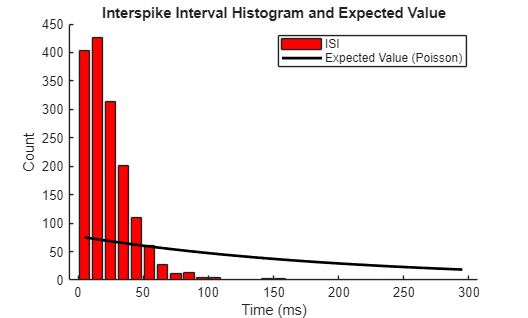

%% 2.2 Interspike Intervals
all_isi = [];

for i = 1:length(mtSpikeTimes)
    spike_times = mtSpikeTimes{i} * 1000; % ms
    if isempty(spike_times)
        continue;
    end
    first_spike = spike_times(1);
    spike_range = spike_times(spike_times > first_spike & spike_times <= first_spike + 300);

    if length(spike_range) > 1
        isi = diff(spike_range);
        all_isi = [all_isi, isi];
    end
end

figure;
hold on;
bins = 0:10:300;
counts = histcounts(all_isi, bins);
bin_centers = bins(1:end-1) + diff(bins)/2;
bar(bin_centers, counts, 'FaceColor', 'red');

% Possion calculations
lambda = avg_firing_rate_300;
t = bin_centers / 1000; % convert from ms to seconds
pdf = lambda * exp(-lambda * t);

bin_width = 10 / 1000; % 10ms bins like we did above
expected_vals = pdf * length(all_isi) * bin_width;
plot(bin_centers, expected_vals, 'k', 'LineWidth', 2);

set(gca, 'FontName', 'Arial');    
xlabel('Time (ms)');
ylabel('Count');
title('Interspike Interval Histogram and Expected Value');

legend('ISI', 'Expected Value (Poisson)');
box off;